clear all
close all
F=5/2;
sigmax=spinOp(F,'x');
sigmay=spinOp(F,'y');
sigmaz=spinOp(F,'z');

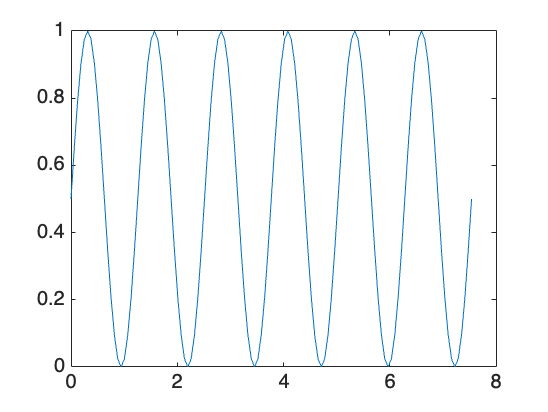

initial=([1 0 0 0 0 1]./sqrt(2))';
ham1=0.01*sigmax+1*sigmaz+0.5*sigmaz^2;
ham2=sigmax+sigmax^2;
timelist=[0:0.1:12].*pi/5;
for i=1:length(timelist)
    precess_state=ham_evolve(ham1,initial,timelist(i));
    final_state(:,i)=ham_evolve(ham2,precess_state,pi/2);
    
end
pop_state=abs(final_state).^2;

plot(timelist,pop_state(1,:));

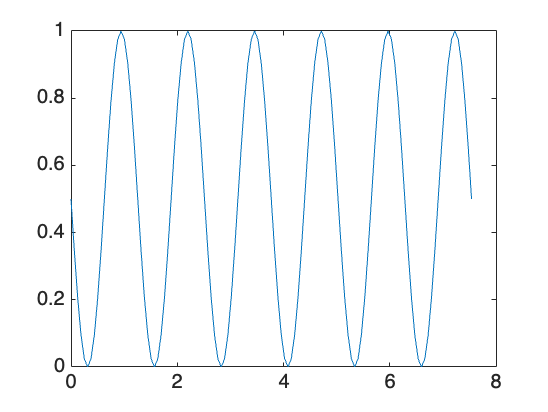

plot(timelist,pop_state(6,:));

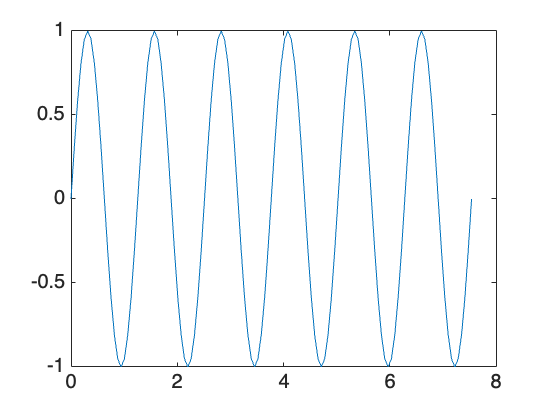

plot(timelist,(pop_state(1,:)-pop_state(6,:))./(pop_state(1,:)+pop_state(6,:)));

function final=ham_evolve(ham,initial,time)
try
    final=expm(-1i*ham.*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end